## **Figures 4a, 4b**

**Notes on the method: **First we find the reliability function, then the pdf of FPTs by numerically taking its derivative. We then find the mean and variance of the FPT pdf. Note that there is a built in check to make sure the time domain is long enough. Additionally, an adequate mesh density is needed in order to produce a resolution high enough to record the points by which the majority of the pdfs density is contained, so when the time domain is extended, the number of points in the mesh is increased as well.

**Run Time: **25 Minute Run Time

**Requirements: **thresholdfun.m, parameters.m all need to be in the working directory so that this script can call them

% Make Global so our DE Can Change Easily
clear;
global i;
global a;

% define colors
col1 = (1/255)*[62, 76, 94]; %charcoal
col2 = (1/255)*[219, 127, 103]; %burnt orange
col3 = (1/255)*[111, 143, 114]; %green

xinit=0.3; % initial condition
n=400; %400 number of a vals considered (for deterministic model, consider n/2)

a=linspace(0.022,0.024,n);
betas = thresholdfun(a);

% store MFPT and var[FPT] values, one for each value of a
mfptVals = zeros(length(a),1);
varVals = zeros(length(a),1); 

%This is our initial terminal time for evaluation of the p.d.e. which retrieves 
%the reliability function. n0 is the initial number of points. 
tf0 = 150000;
n0 = 15000;

%Iterate through the different values of a
for i = 1:length(a)
    i % output n so I can see how far we are in the loop
   
    %Integral of the p.d.f. for first passage time. 
    int = 0;
   
    %Extend the terminal time for evaluation and the number of points until we
    %get within a tolerance .99 for integration of the pdf.
    while(int < .99)
        
        %Define x0 & time domain for pde. 
        x0 = linspace(0,betas(i),500);
        t = linspace(0,tf0,n0);
    
        %Find Solution
        sol = pdepe(0,@eqn,@ic,@bc,x0,t);
    
        %Find Our Initial Value Used in the Paper
        distFromX0 = zeros(1,length(x0));
    
        %Determine the Distance of Each x0 from our chosen initial condition of xinit 
        for j = 1: length(x0)
        distFromX0(j) = abs(xinit-x0(j));
        end

        %Select the point closest to xinit
        [minDistFromX0,ourX0] = min(distFromX0);
    
        %Get Reliability Function & PDF
        reliability = sol(:,ourX0);
        pdf = -gradient(reliability,t);
    
        %Integrate pdf
        int = cumtrapz(t,pdf);
    
        %Make our time evaluation larger if not in tolerance but maintain
        %density
        if(int < .99)
            tf0 = tf0 + 100
            n0 = n0 + 10;   
        end
    end

    %%%%%%%%%%%Get MFPT Value for our iteration using expectation%%%%%%%%%%%

    expf = 0*pdf;

    %Get X*f(x) 
    for j = 1: length(pdf)
        expf(j) = pdf(j)*t(j);
    end

    %Integrate X*f(x) to get Expectation
    mfptVals(i) = trapz(t,expf);

    %%%%%%%%%%% Get variance of FPTs for our iterations %%%%%%%%%%%

    varint = 0*pdf;

    %Get (x-mu)^2*f(x) 
    for j = 1: length(pdf)
        varint(j) = pdf(j)*(t(j)-mfptVals(i))^2;
    end

    %Integrate X*f(x) to get Expectation
    varVals(i) = trapz(t,varint);
        
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6


% save the MFPT and var of FPT vectors 
%csvwrite('mfptVals.txt',mfptVals) 
%csvwrite('varVals.txt',varVals) 


Find the FPTs for the deterministic model

global det_a
det_a = linspace(min(a),0.023051895,n/2) % the second input is just adjacent to the asymptote

det_a =     0.0220    0.0225    0.0231


det_betas = thresholdfun(det_a);
fpt = zeros(1,length(det_a));

%Fixed Params for DEs
tmax = 5000;

%Sim DEs & Get FPTs
for i = 1:length(det_a)
    
    [t,y] = ode45(@DE,[0 tmax],xinit, odeset('RelTol',1e-10));
    
    %Get FPTS
    for j = 1: length(y)
        
        if(y(j) > det_betas(i))
            
            fpt(i) = t(j);
            break;
        end
        
    end
    
end


Make plot of the MFPT against *a*

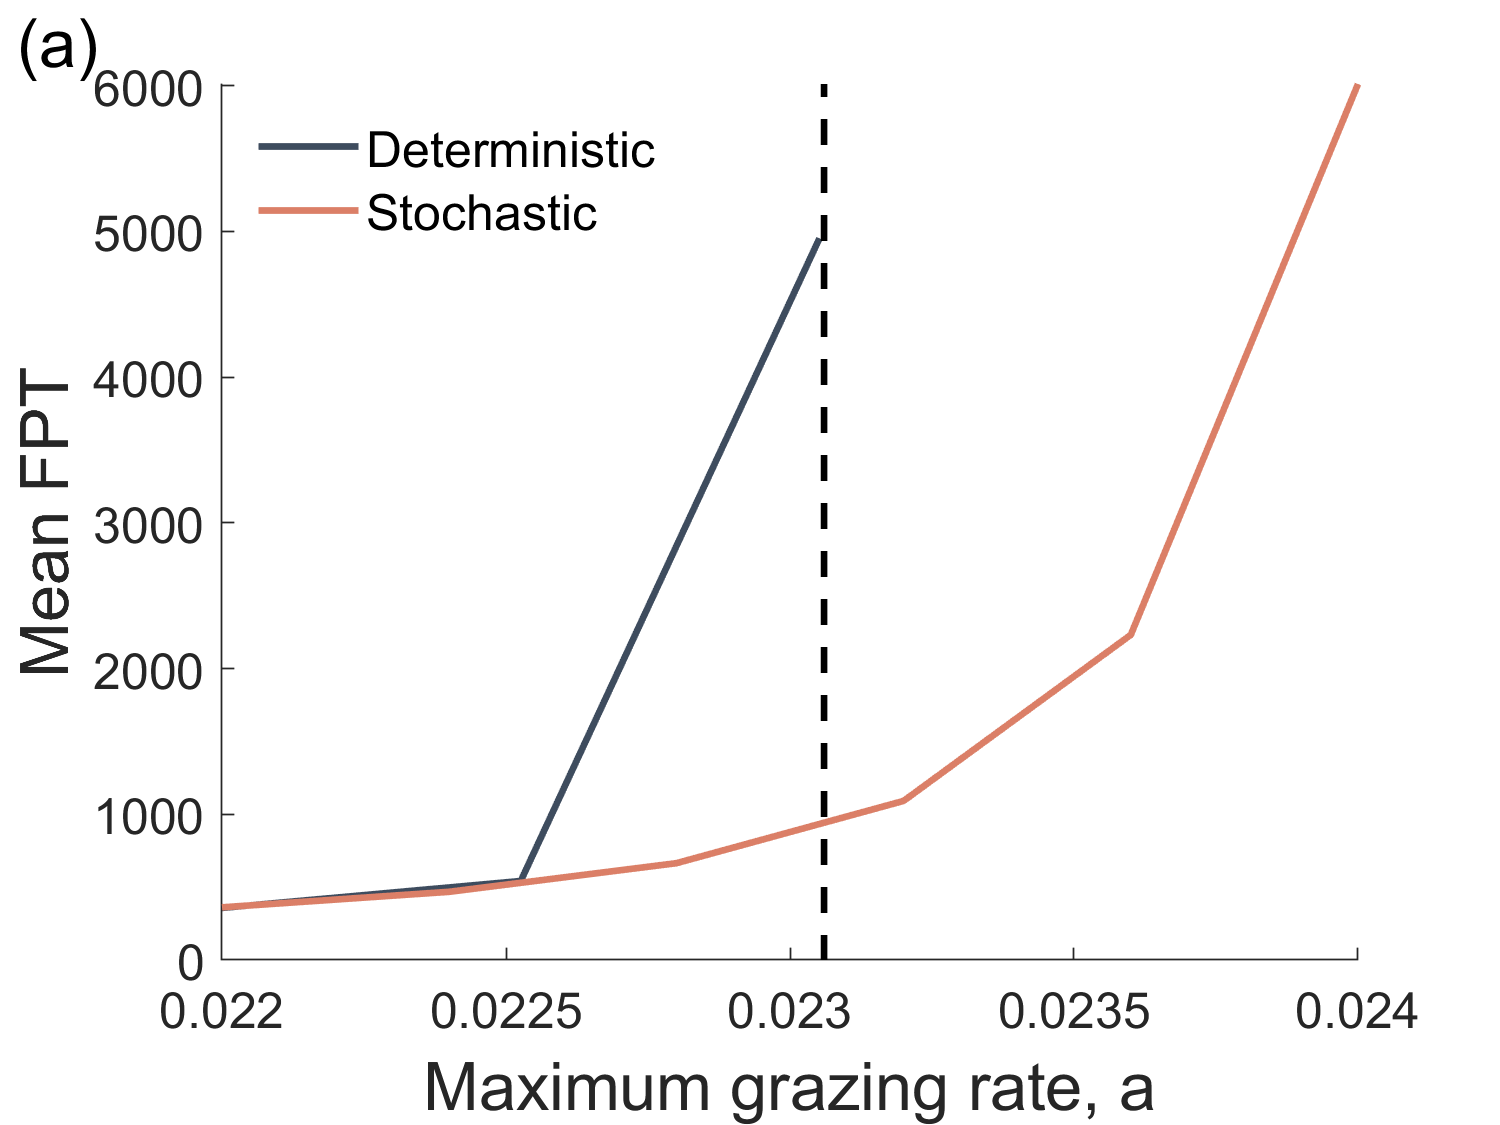


figure
hold on
plot(det_a,fpt,'Color',col1,'LineWidth',2) % deterministic curve
plot(a,mfptVals,'Color',col2,'LineWidth',2) % stochastic curve

%Plot Asymptote
asym = line([.02306 .02306],[0 max(mfptVals)],'linestyle','--','Color','black','LineWidth',2);
asym.Annotation.LegendInformation.IconDisplayStyle = 'off';

%Modifications
legend('Deterministic','Stochastic',"FontSize",15,'Location', 'Northwest', 'Box', 'off');
set(gca,'FontSize',15);
xlim([min(a) max(a)])
ylim([0 max(mfptVals)])
xlabel('Maximum grazing rate, a','FontSize',20);
ylabel('Mean FPT','FontSize',20);

% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(a)', 'FontSize', 20, 'EdgeColor', 'none');
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size

%exportgraphics(gcf, 'Fig4a.pdf', 'BackgroundColor', 'none');


Now make plot of Var[FPT] against a

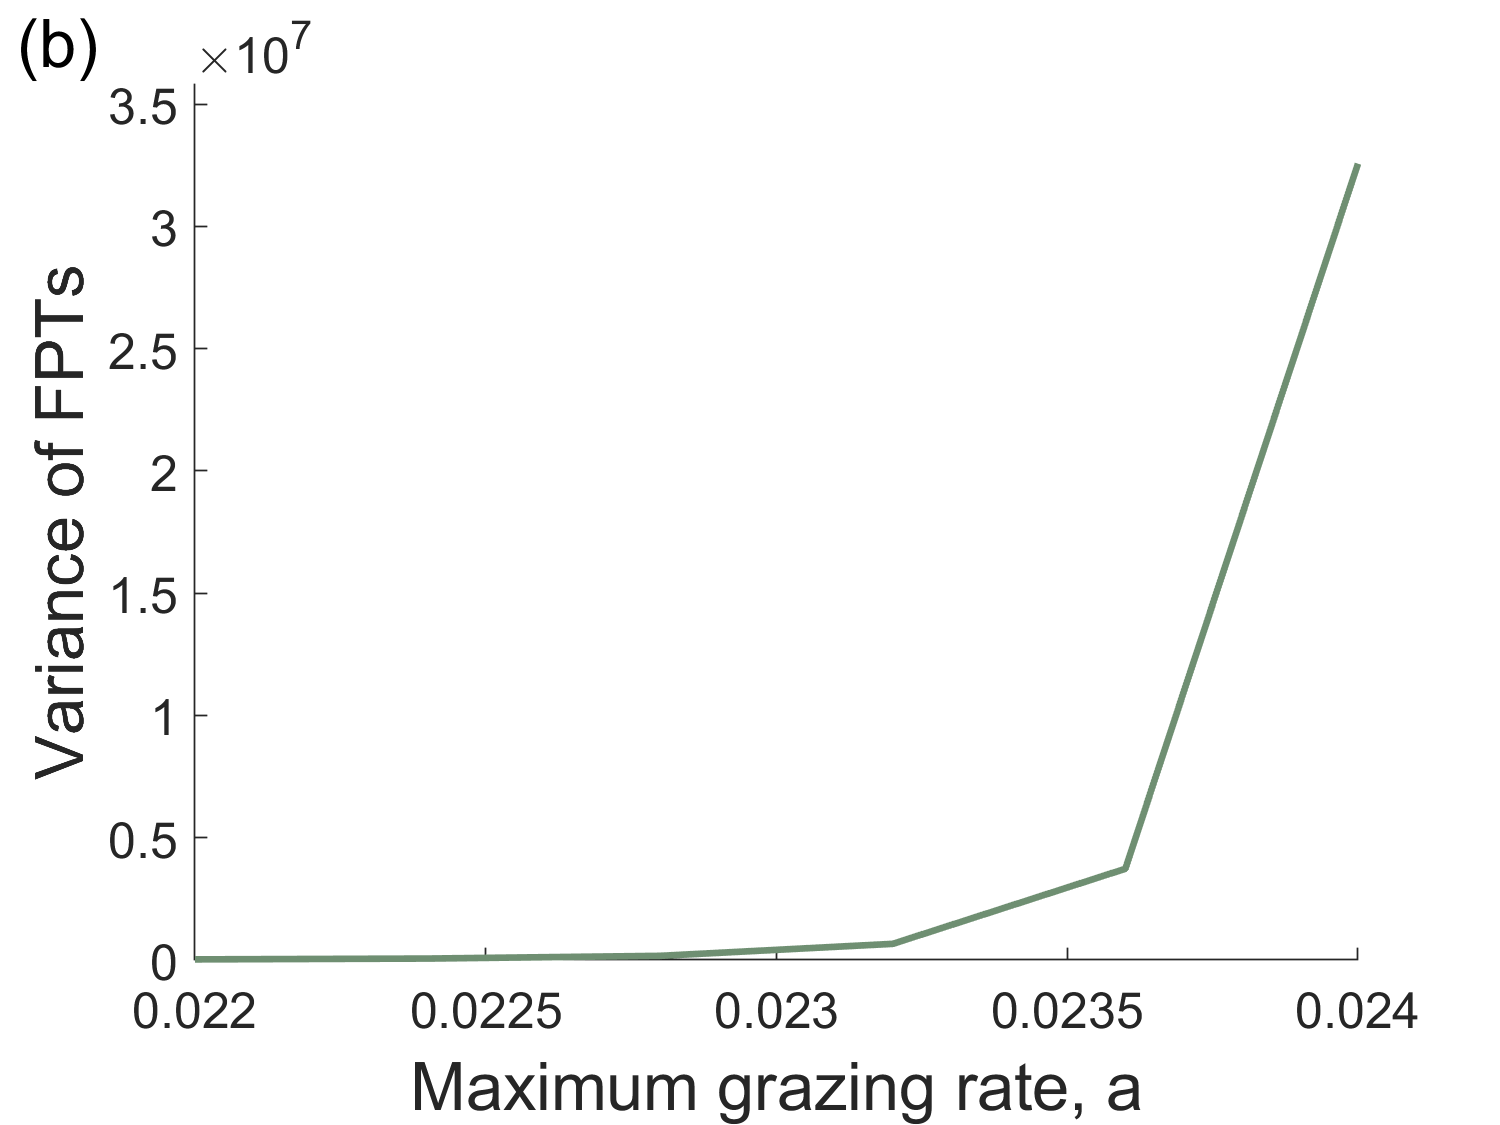

figure
hold on
plot(a,varVals,'Color',col3,'LineWidth',2)

set(gca,'FontSize',15);
xlim([min(a) max(a)])
ylim([0 max(varVals)*1.1])
xlabel('Maximum grazing rate, a','FontSize',20);
ylabel('Variance of FPTs','FontSize',20);

% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
annotation('textbox', [0, 0.95, 0.06, 0.06], 'String', '(b)', 'FontSize', 20, 'EdgeColor', 'none');
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size

%exportgraphics(gcf, 'Fig4b.pdf', 'BackgroundColor', 'none');


Check whether MFPT of Var of FPTs varies exponentially with a 

% % Sample data
% x = a;  % Independent variable
% y = mfptVals;  % Dependent variable
% 
% % Create a fittype for the exponential function
% % You can choose to fit to either 'exp1' (single-exponential) or 'exp2' (double-exponential) as per your data.
% % In this example, we'll use 'exp1'.
% f = fittype('a * exp(b * x)', 'independent', 'x', 'dependent', 'y');
% f = fittype('a1 * x^a2', 'independent', 'x', 'dependent', 'y');
% 
% % Fit the data to the exponential function
% fitResult = fit(x(:), y(:), f);
% 
% % Display the fitted parameters
% a1 = fitResult.a1;
% a2 = fitResult.a2;
% 
% % Check goodness of fit (R-squared value)
% rsquared = 1 - sum((fitResult(x) - y).^2) / sum((y - mean(y)).^2);
% 
% % Plot the data and the fitted curve
% figure;
% plot(x, y, 'o', 'DisplayName', 'Data');
% hold on;
% plot(x,fitResult(x), 'r-', 'DisplayName', 'Exponential Fit');
% xlabel('x');
% ylabel('y');
% legend('show');
% 
% % Check if it's an exponential curve (you can set a threshold for R-squared)
% if rsquared > 0.95
%     disp('The data follows an exponential curve.');
% else
%     disp('The data does not follow an exponential curve.');
% end


**Notes on Functions: **eqn is the PDE, u0 is the initial condition function, bc is the Boundary Condition Functions, and DE is the deterministic ODE

function [c,f,s] = eqn(x0,t,P,DPDx0)

    global a;
    global i;

    %Parameters
    [r,K,h,q,sigma] = parameters();
    
    %Time Derivative is Not Scaled
    c = 1;

    %Diffusion Vector Transformed for BK
    f = DPDx0*(.5*sigma^(2)*x0^(2));

    %Drift Vector Transformed for BK
    s = (r*x0*(1-(x0/K)) - (a(i)*x0^(q))/(x0^(q) + h^(q)) - (sigma^(2) * x0))*DPDx0;

end

function u0 = ic(x0)

%The probability we're in target region at t = 0 is 1 
%Independent of the x0
u0 = 1;

end

function [pl,ql,pr,qr] = bc(x0l,Pl,x0r,Pr,t)

%Probability of Being in Target Space if we Start @ 0 for any time is 1
%given 0 should act like a steady state
pl = 1-Pl;
ql = 0;

%Probability of Being in Target Space if we Start @ mu = 0
pr = Pr;
qr = 0;
end

function f = DE(t,x)

global det_a;
global i;

%Parameters
[r,K,h,q,~] = parameters();

f = r * x * (1-(x/K)) - (det_a(i)*x^(q))/(x^(q) + h^(q));

end
